# CLASE_02_a >> Trabajando con señales

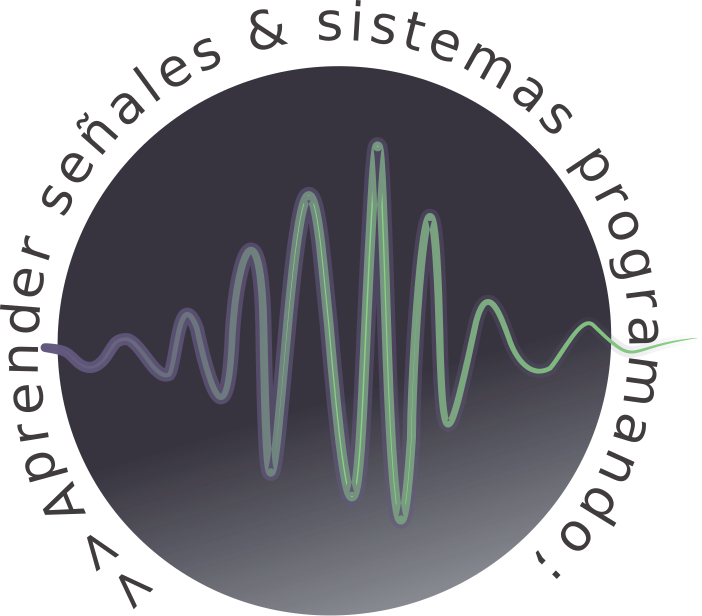

# Temario:

- Representación númerica.

- Energía y potencia.

- Matrices.

- Secuencias.

- Señales discretas básicas.

- Señales continuas básicas.

# Representación númerica

Las computadoras suelen usar un sistema binario de representación de números, debido a que están fabricados con componentes electrónicos que son capaces de representar solo dos estados diferentes. Además, este sistema de representación es discreto, lo que supone un problema para representar números reales en un ordenador. **Si estamos usando un método numérico para resolver un problema de ingeniería o científico, es importante entender cómo se representa la información en un computadora para controlar el error cometido en el cálculo**. 

Un transistor es un elemento electrónico biestable, es decir, es capaz de representar dos estados. Mediante impulsos eléctricos es posible leer el estado de un transistor, y cambiarlo. Debido a esta característica, en la actualidad todas **las computadoras funcionan con un sistema de representación numérica binario**. Los transistores actuales son microscópicos, por lo que un ordenador puede contener cientos de millones de transistores, lo que posibilita la representación de números muy grandes. En la práctica, las arquitecturas modernas funcionan con números de 64 bits [Mat.caminos.upm.es, 2017]. 

El bit es la unidad mı́nima de información empleada en dispositivos digitales. Un **bit **es capaz de tener dos estados: 0 (cero) y 1 (uno). Por lo tanto, para representar más cantidad de valores es necesario usar más bits. Si se usan 2 bits se pueden representar $4=2^2$ valores distintos: 00, 01, 10, 11. Si se usan 4 bits se pueden representar $16=2^4$ valores distintos: 0000, 0001, 0010, 0011, . . . etc. En general, con n bits se pueden representar $2^n$ valores distintos.

Los bits se suelen agrupar en grupos de 8, formando un **byte**. Para almacenar datos, a su vez, se suelen considerar agrupaciones de 4 u 8 bytes (32 ó 64 bits), a las que se llama **palabras. **Estas agrupaciones determinan el conjunto de valores que se pueden almacenar en ellas:

- En 4 bytes (32 bits) se pueden almacenar: 

2^32 - 1 % (restamos 1 para contar el cero también)

ans = 4.2950e+09

intmax('uint32') % Números naturales

ans = 4294967295

- En 8 bytes (64 bits) se pueden almacenar: 

2^64 - 1 % (restamos 1 para contar el cero también)

ans = 1.8447e+19

intmax('uint64') % Números naturales

ans = 18446744073709551615

## Almacenamiento de números enteros

Para representar los números enteros tenemos que tener en cuenta que es necesario también **incluir el signo**. Como solo tenemos dos signos posibles (positivo o negativo), es posible representar el signo con un bit. 

Los números enteros que se almacenan en palabras de 32 bits (4 bytes) son distribuidos de la siguiente manera (igual analisis se puede realizar con 64 bits, 8 ):

- 1 bit para el signo del número (0 si es positivo, 1 si es negativo).

- los 31 bits restantes son para almacenar los dı́gitos binarios del número sin signo.

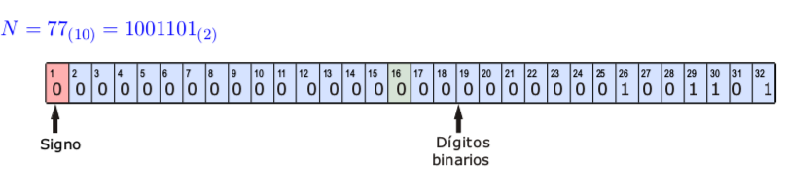

El mayor entero positivo que se puede almacenar con este sistema es:

a = intmax('int32')

a = 2147483647

El menor entero negativo que se puede almacenar con este sistema es:

b = intmin('int32')

b = -2147483648

Los números enteros que se pueden representar en MATLAB son:

A = dec2bin(int8(2^7-1))

A = 1111111

a = int16(2)

a = 2

C = int32(1)

C = 1

D = int64(1)

D = 1

E = uint8(257) % ¿Cual es el valor maximo que puedo representar?

E = 255

F = uint64(1)

F = 1

## Almacenamiento de números reales

La representación de los números enteros y naturales es relativamente sencilla. Después de todo, al ser discretos, se representan bien en el sistema binario. El único inconveniente es que existe un límite para los números que podemos representar. ¿Pero qué ocurrirá con los números reales? **El conjunto de los números reales no es numerable,** es decir, entre dos números reales dados existe una cantidad infinita de números reales. ¿Cómo podemos representar esta cantidad infinita de números en una computadora con un número finito de transistores [Mat.caminos.upm.es, 2017]. **Los números reales, habitualmente se representan en punto flotante **(en inglés, floating point). Se trata de un modo “normalizado” de representación de números con parte decimal y entera. **Consiste en trasladar la coma (o punto) decimal hasta la posición de la primera cifra significativa (la primera, comenzando por la izquierda, que no es nula) a la vez que se multiplica el número por la potencia adecuada de la base de numeración.**

Es decir, la representación en punto flotante es **similar a la notación científica**. Por ejemplo, el número 12345 se representaría por una mantisa formada por los números 12345 y el exponente 1. El número se obtendría multiplicando$12345 \cdotp 10^1$. Otro ejemplo sería el número 0,00675, cuya representación constaría de la mantisa 675 y del exponente -3; el número se obtendría como $675 \cdotp 10^{-3}$.


$$R=(\pm) 0. m_1m_2m_3 \cdots m_k \cdotp2^{\pm e}$$


donde $m_1m_2m_3...m_k$se llama la **mantisa **y el número $e$ (que escribimos aquı́ en forma de entero decimal) es el **exponente,** es decir, el número de lugares que hay que trasladar la coma a derecha o izquierda para obtener el número inicial. Obsérvese que $m_1$ tiene que ser siempre igual a 1, ya que es, por definición, la primera cifra no nula empezando por la izquierda.


$$R = 5,625_{(10)} =101,101_{(2)}=0,101101 \cdotp 2^3$$


## Precisión doble y simple (IEEE 754)

**En arquitecturas de 64 bits, la mantisa, el signo de la mantisa, el exponente y el signo del exponente**, pueden ocupar como máximo 64 bits. Esto hace que los números más grande y pequeño que podemos representar en punto flotante sean más pequeños que en el caso de los enteros y los naturales.

Para almacenar dicho número, los 32 bits de una palabra se distribuyen de la siguiente manera (igual analisis se puede realizar con 64 bits):

- 1 bit para el signo del número (0 si es positivo, 1 si es negativo).

- 23 bits para la mantisa. Como $m_1$ es siempre igual a 1 se utiliza el pequeño “ truco” de no almacenarlo. Ası́, aunque se almacenan 23 cifras binarias se “conocen” en realidad 24.

- 8 bits para el exponente con su signo (se guarda codificado como un número entero).

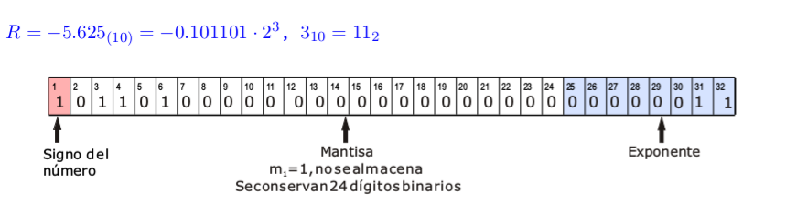

realmax('single')

ans = 3.4028e+38

realmin('single')

ans = 1.1755e-38

realmax('double')

ans = 1.7977e+308

realmin('double')

ans = 2.2251e-308

## Error debido a la presición

En ambos casos, **como todo el espacio que ocupa el número tiene que repartirse entre mantisa y exponente, existe también un límite en la precisión que podemos representar.** Es decir, los números en punto flotante son discretos. Por ejemplo, si tomamos un número con infinitos decimales, inevitablemente se perderán decimales al representarlo en punto flotante. Este error se conoce como **error de redondeo**, ya que el número decimal se redondea ignorando los decimales de menor peso.

eps('single') % Vacı́os entre números representables

ans = 1.1921e-07

eps('double')

ans = 2.2204e-16

Para un poco más de información ([Representación númerica en un ordenador - MateWiki](https://mat.caminos.upm.es/wiki/Representaci%C3%B3n_num%C3%A9rica_en_un_ordenador))

# Energía y potencia

En muchas aplicaciones, aunque no en todas, las señales que examinamos están directamente realacionas con cantidades físicas que capturan potencia y energia de un sistema físico [Oppenheim A.,pp. 5-7, 1998]. Por ejemplo, el voltaje y la corriente a través de un resistor con resistencia R, entonces **la potencia istantánea** es:


$$p(t)=v(t)i(t)=\frac {1}{R}v^2(t)$$


Entonces la **energía total **gastada durante un **intervalo de tiempo continuo** $[t_1:t_2]$se define como:


$$E[p(t)]_{t_1 \rightarrow t_2} = \int_{t_1}^{t_2} p(t) dt = \int_{t_1}^{t_2} \frac {1}{R} \vert v(t) \vert^2 dt$$


La **potencia promedio** durante el mismo i**ntervalo de tiempo continuo** $[t_1:t_2]$ es:


$$P[p(t)]_{t_1 \rightarrow t_2} = \frac {1}{t_2-t_1} \int_{t_1}^{t_2} p(t) dt = \frac {1}{t_2-t_1} \int_{t_1}^{t_2} \frac {1}{R} \vert v(t) \vert^2 dt$$


De lo presentado anteriormente se desprende la definición de **energia total **durante un **intervalo de tiempo continuo** $[t_1:t_2]$:


$$E[x(t)]_{t_1 \rightarrow t_2} = \int_{t_1}^{t_2} \vert x(t) \vert^2 dt$$


En el **caso discreto** de una señal $x[n]$en el intervalo $[N_1:N_2]$ se define como:


$$E[x[n]]_{N_1 \rightarrow N_2} = \sum_{n \rightarrow N_1}^{N_2} \vert x[n] \vert^2$$


Y la definición de la **potencia promedio** durante el mismo i**ntervalo de tiempo continuo** $[t_1:t_2]$:


$$P[x(t)]_{t_1 \rightarrow t_2} = \frac {1}{t_2-t_1} \int_{t_1}^{t_2} \vert x(t) \vert^2 dt$$


En el **caso discreto** de una señal $x[n]$en el intervalo $[N_1:N_2]$ se define como:


$$P[x[n]]_{N_1 \rightarrow N_2} = \frac {1}{N_2-N_1+1} \sum_{n \rightarrow N_1}^{N_2} \vert x[n] \vert^2$$


Con $\vert x(t) \vert$la **magnitud de una señal** continua cualquiera o cualquier señal discreta $\vert x[n] \vert$.

En muchos sistemas nos interesa examinar la **potencia y energía de señales** en un i**ntervalo de tiempo infinito.**

**Energía total para tiempo continuo:**


$$E_\infty=\lim_{T \to \infty }\int _{-T}^{T} \vert x(t) \vert^2 dt=\int _{-\infty}^{\infty} \vert x(t) \vert^2 dt$$


**Energía total para tiempo discreto:**


$$E_\infty=\lim_{N \to \infty }\sum _{n=-N}^{N} \vert x[n] \vert^2 =\sum_{n=-\infty}^{\infty} \vert x[n] \vert^2$$


**Potencia promedio para tiempo continuo:**


$$P_\infty=\lim_{T \to \infty } \frac{1}{2T} \int _{-T}^{T} \vert x(t) \vert^2 dt$$


**Potencia promedio para tiempo discreto:**


$$P_\infty=\lim_{N \to \infty } \frac{1}{2N+1} \sum_{n=-N}^{N} \vert x[n] \vert^2 $$


El analisis de las señales x(t) o x[n] en un intervalo infinito permite identificar **tres clases importantes de señales** : 

- Son señales con **energía finita (o señales de energía)**, si y sólo si, $0<E_\infty<\infty$ (**energía total finita**). Una señal de este tipo debe tener una **potencia promedio igual a cero**, ya que, en el caso de tiempo continuo, por ejemplo, vemos que:


$$P_\infty=\lim_{T \to \infty}\frac{E_\infty}{2T}=0 $$


- Son señales con **potencia promedio finita (señales de potencia)**, si y sólo si $0<P<\infty$ (**potencia promedio finita**). Entonces, si $P_\infty >0$, por necesidad $E_\infty \to \infty$. Esto tiene sentido, ya que si se tiene una energía promedio por unidad de tiempo diferente de cero, entonces integrando o sumando en un intervalo de tiempo infinito produce una cantidad de **energía infinita**. Por ejemplo, la señal constante x[n] = 4 tiene energía infinita, pero la potencia promedio es $P_\infty=16$. Otro ejemplo de esto son las señales periodicas.

- Señales con **energia** y **potencia promedio infinita**, por ejemplo la señal x(t) = t.

## Ejercicios de la guía n°1 (script_02_01)

Los siguientes ejercicios de la guia n°1, pueden ser resueltos con MATLAB:

1) Determinar la energía y la potencia de las siguientes señales:  

a) $x(t)=3e^{-2t}u(t)$

b) $x(t)=2cos(\omega_0t+\pi)$

c) $x[n]=2u[n] $  (u[n] = Escalon unitario o Heaviside discreta)

**Symbolic Math Toolbox**, una herramienta muy útil:

%doc syms

En matemáticas y ciencias de la computación, el **álgebra computacional**, también conocida como **cálculo simbólico** o **cálculo algebraico**, es un área científica que se refiere al estudio y desarrollo de algoritmos y software para la **manipulación de expresiones matemáticas** y otros objetos matemáticos. Aunque, hablando con propiedad, el álgebra computacional debe ser un sub-campo de la computación científica, ellos son considerados generalmente como campos distintos, porque la **computación científica** se basa generalmente en el análisis numérico con **números aproximados en punto flotante**; mientras que, el **álgebra computacional **enfatiza el **cálculo *****exacto***** con expresiones que contengan variables y por lo tanto son manipulados como símbolos (de ahí se debe el nombre de *****cálculo simbólico*****).**

Veamos un ejemplo:


$$x(t)=2e^{-t}u(t)$$


syms t T h % asignación

x = sym(2*exp(-t))  % definición

fplot(x,[0,10])  % gráfico de funciones, definidas simbolicamente
hold on
fplot(heaviside(h), [-1, 10])
ylabel('x(t)')
xlabel('t')
legend('2e^{-t}','u(t)')
grid on

c =      1     2     3     4


hold off

d =      5     6     7     8



$$E_\infty=2\int _{0}^{\infty} \vert e^{-t} \vert^2 dt$$


E = int(x^2,'t',0,inf);

d =      1     2     3     4
     5     6     7     8


Ene = simplify(E)

e =      1
     2



$$P_\infty=\lim_{T \to \infty } \frac{1}{2T} 4 \int _{0}^{T} \vert e^{-t} \vert^2 dt$$


P = limit((1/(2*T))*(int(x^2,'t',0,T)),T,inf);

f =      1     2     3     4     1
     5     6     7     8     2


Pot = simplify(P)

g =      1     2     3     4     1     1     2     3     4
     5     6     7     8     2     5     6     7     8


% open ('script_02_01.m')

# **Matrices**

Retomando las matrices, el gran potencial de MATLAB.

Limpiar command window

clc

ans = 256

Limpiar workspace

clear all

ans =      2
   144
    99
    25



$$c = \pmatrix{1&2&3&4} \quad ,$$



$$d = \pmatrix{5&6&7&8} \quad,$$



$$d = \pmatrix{1&2&3&4\cr 5&6&7&8} \quad,$$



$$f = \pmatrix{1&2&3&4&1\cr 5&6&7&8&2} \quad,$$



$$e = \pmatrix{1 \cr 2}\quad,$$



$$g = \pmatrix{1&2&3&4&1&1&2&3&4\cr 5&6&7&8&2&5&6&7&8} \quad,$$


c = [1 2 3 4]

ans =      2   144    99    25


d = [5,6,7,8]
d = [c;d]
e = [1;2]
f = [d e]

ans =     2.0000  126.0000   64.6000
    8.0000   13.8000    4.0000
    4.0000  576.0000  127.4000


g = [f d]

ans =   150.6000  312.7000   85.9900
   32.0000   41.8000   18.6000
  488.0000  961.6000  275.4000


## Operando con Matrices

Dada las siguientes matrices:


$$F1 = \pmatrix{12&12&3&45} \quad ,$$
 
$$F2 = \pmatrix{142&12&31&45} \quad ,$$



$$C1 =\pmatrix{42\cr2\cr3\cr5} \quad , $$
 
$$C2 =\pmatrix{42\cr2\cr3\cr5} \quad .$$


Probar las siguientes operaciones:


$$F1+C1$$



$$F2+C1'$$



$$\sum_{n=1}^{\infty}{F1(n)$$



$$\prod_{n=1}^{\infty}F2(n)$$



$$T = \pmatrix{e^{F1(1)}&e^{F1(2)}&e^{F1(3)}&e^{F1(4)}}$$


Ayuda: 

help sum

ans =      1     4
     9    16


help prod  % productoria

ans =      7    10
    15    22


help exp

## Un poco más de matrices...


$$\pmatrix{4&27&3&5} .*\pmatrix{42\cr2\cr3\cr5}= error$$
          
$$\pmatrix{4&27&3&5} *\pmatrix{42\cr2\cr3\cr5}= 256$$


%[4 27 3 5].*[42; 2; 3; 5] % Multiplicación elemento por elemento
[4 27 3 5]*[42; 2; 3; 5]


$$\pmatrix{2\cr2\cr3\cr5} .*\pmatrix{1\cr72\cr33\cr5}=\pmatrix{2\cr144\cr99\cr25} $$


[2; 2; 3; 5].*[1; 72; 33; 5]

n =     -3    -2    -1     0     1     2     3     4



$$\pmatrix{2&2&3&5} .*\pmatrix{1&72&33&5}=\pmatrix{2&144&99&25} $$


[2 2 3 5].*[1 72 33 5]


$$\pmatrix{2&2&3&5} *\pmatrix{1&72&33&5}=error$$


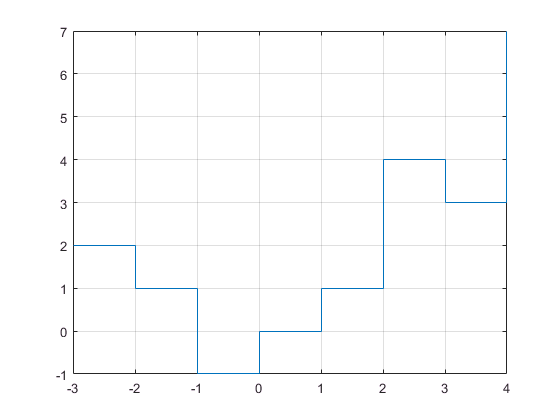

%[2 2 3 5]*[1 72 33 5]


$$\pmatrix{1&21&32.3\cr2&6&2\cr2&72&98} .*\pmatrix{2&6&2\cr4&2.3&2\cr2&8&1.3}=?$$
         
$$\pmatrix{1&21&32.3\cr2&6&2\cr2&72&98} *\pmatrix{2&6&2\cr4&2.3&2\cr2&8&1.3}=?$$


[1 21 32.3; 2 6 2; 2 72 98].*[2 6 2; 4 2.3 2; 2 8 1.3]
[1 21 32.3; 2 6 2; 2 72 98]*[2 6 2; 4 2.3 2; 2 8 1.3]


$$\pmatrix{1&2\cr3&4} .\^2 =?$$
   
$$\pmatrix{1&2\cr3&4} \^2 =?$$


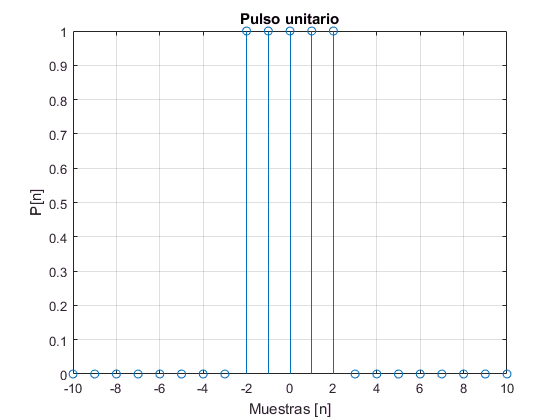

[1 2; 3 4].^2

[1 2; 3 4]^2

# Secuencias

**Las señales pueden ser clasificadas** en analogicas y discreta. Una señal **analogica** es denotada por $x\left(t\right)$, donde la variable t (**variable independiente**) puede ser representada como alguna cantidad fisica continua. En nuestro caso de estudio representa el **tiempo en segundos (continua)**. En el caso de una señal **discreta** se denota por $x\left\lbrack n\right\rbrack$, donde la variable **n son valores enteros y representa instancias de tiempo discreto**. A lo largo de este apunte haremos mayor hicapié en las señales discretas, para lo cual vamos a definir una **secuencia discreta como**:


$$x\left\lbrack n\right\rbrack =\left\lbrace x\left(x\right)\right\rbrace =\left\lbrace \ldotp \ldotp \ldotp ,x\left(−1\right),x^{\uparrow }{} \left(0\right),x\left(1\right),\ldotp \ldotp \ldotp \right\rbrace$$


**MATLAB, puede representar solo secuencias de duración finita, por medio de un vector fila**. Sin embargo un vector no tiene informacion sobre la posicion $n$. La forma correcta de representar una secuencia requiere de dos vectores, uno para $x$ y otro para $n$. Por ejemplo la secuencia $x\left\lbrack n\right\rbrack =\left\lbrace 2,1−1,{0^{\uparrow }} ,1,4,3,7\right\rbrace$puede ser representada por:

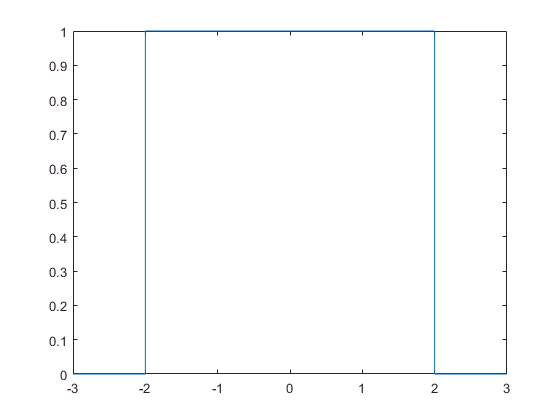

x = [2,1,-1,0,1,4,3,7]; % secuencia - rango
n = -3:1:4  % indices (o posición) - dominio

stairs(n,x)
grid on

--- help for single/dirac ---

 dirac  Delta function.
     dirac(X) is zero for all X, except X == 0 where it is infinite.
     dirac(n,X) is the nth derivative of dirac(X).
     dirac(X) is not a function in the strict sense, but rather a
     distribution with int(dirac(x-a)*f(x),-inf,inf) = f(a) and
     diff(heaviside(x),x) = dirac(x).
     See also heaviside.

    Other functions named dirac



# Señales discretas básicas

## **Impulso unitario**


$$\delta[n]=\begin{cases} 1, \text{para } n=0 \\  0, \text{para  } n\neq 0 \end{cases}$$
 
$$=\text{ }\left\lbrace \ldotp \ldotp \ldotp ,0,0,1^{\uparrow } ,0,0,\ldotp \ldotp \ldotp \right\rbrace$$



$$\delta \left\lbrack n−n_0 \right\rbrack =\left\lbrace \begin{array}{c}
1 & n=n_0 \\
0 & n\ne n_0 
\end{array}\right.$$


n = -5:10;

--- help for single/heaviside ---

 heaviside    Step function.
     heaviside(X) is 0 for X < 0 and 1 for X > 0.
     The value heaviside(0) is 0.5 by default. It
     can be changed to any value v by the call
     sympref('HeavisideAtOrigin', v).
 
     heaviside(X) is not a function in the strict sense.
     See also dirac.

    Other functions named heaviside



delta = zeros(1,length(n));

--- help for single/triangularPulse ---

    Y = triangularPulse(X) is the symmetric triangular pulse
    over the interval from -1 to 1.
 
    Y = triangularPulse(A,C,X) is the symmetric triangular pulse
    over the interval from A to C.
 
    Y = triangularPulse(A,B,C,X) is the general triangular pulse
    over the interval from A to C with its maximum at B.
 
    It is 0 if X <= A.
    It is (X-A)/(B-A) if A <= X <= B.
    It is (C-X)/(C-B) if B <= X <= C.
    It is 0 if X >= C.
 
    Example:
       triangularPulse(-2, 0, 3, -4)       returns  0
       triangularPulse(-2, 0, 3,  0)       returns  1
       triangularPulse(-2, 0, 3,  2)       returns  0.3333
       triangularPulse(-2, 0, 3,  3)       returns  0
       syms a x
       triangularPulse(a-1, a+1, a+2, a-1) returns  0
       triangularPulse(a-1, a+1, a+3

[cant, ind] = find(n == 0,1);
delta(ind) = 1;
stem(n,delta); title ('Impulso unitario'); ylabel ('X[n]'); xlabel ('Muestras [n]'); grid on; 

Versión más simple.

delta = [ zeros( 1 ,10 ), 1 , zeros( 1 ,10 ) ];
n = -10:10;
stem(n,delta); title ('Impulso unitario'); ylabel ('X[n]'); xlabel ('Muestras [n]'); grid on; 

Versión con función predefinida.

x = -10:1:10;
y = dirac(x);
idx = y == Inf;  % busco el indice de inf
y(idx) = 1; 
stem(x,y)
grid on

## **Pulso rectangular**


$$P[n]=\begin{cases} 1/\tau, \text{para } \vert n \vert< \tau/2  \\  0, \text{resto  } 
\end{cases}$$
 
$$=\left\lbrace \ldotp \ldotp \ldotp ,0,1,1^{\uparrow } ,1,0,\ldotp \ldotp \ldotp \right\rbrace$$


u = [zeros(1,8), ones(1,5), zeros(1,8)];
n = -10:10;
stem(n,u); title ('Pulso rectangular'); ylabel ('P[n]'); xlabel ('Muestras [n]'); grid on; 

## **Escalon unitario o heaviside discreta**


$$u[n]=\begin{cases} 0, \text{para } n<0  \\  1, \text{para  } n\geq 0 \end{cases}$$
 
$$=\left\lbrace \ldotp \ldotp \ldotp ,0,0,1^{\uparrow } ,1,1,\ldotp \ldotp \ldotp \right\rbrace$$



$$u\left\lbrack n−n_0 \right\rbrack =\left\lbrace \begin{array}{c}
1 & n\ge n_0 \\
0 & n<n_0 
\end{array}\right.$$


u = [zeros(1,10), ones(1,11)];
n = -10:10;
stem(n,u); title ('Escalon unitario'); ylabel ('u[n]'); xlabel ('Muestras [n]'); grid on; 

Versión simbolica.

syms x
fplot(heaviside(x), [-2, 2])
grid on

## **Comprobar las siguientes propiedades**


$$\delta[n]=u[n]-u[n-1]\text{ ,}$$


u1 = [zeros(1,10), ones(1,11)];
u2 = [zeros(1,11), ones(1,10)];
delta = u1-u2;
n = -10:10;
stem(n,delta); title ('Impulso unitario'); ylabel ('X[n]'); xlabel ('Muestras [n]'); grid on; 


$$u[n]=\sum_{m=-\infty}^{n}{\delta[m]} \text{ ,}$$


clear all
u1 = [zeros(1,10), ones(1,11)];
u2 = [zeros(1,11), ones(1,10)];
delta = u1-u2;
u = cumsum(delta);
n = -10:10;
stem(n,u); title ('Impulso unitario'); ylabel ('u[n]'); xlabel ('Muestras [n]'); grid on; 

## Otras señales de interes

**Rampa**


$$r[n]=\begin{cases} n, \text{para } n=0,1,... \\  0, \text{para  } n\neq -1,-2,... \end{cases}$$
 
$$=\text{ }\left\lbrace \ldotp \ldotp \ldotp ,0,0^{\uparrow } ,1{} ,2,3,\ldotp \ldotp \ldotp \right\rbrace$$


n = [-4:5]; r= [zeros(1,find(n == 0)) 1:5];
stem(n,r); title ('Rampa'); ylabel ('r[n]'); xlabel ('Muestras [n]'); grid on; 

**Secuencia exponencia de valores reales**


$$x\left\lbrack n\right\rbrack =a^n ,\text{ }\forall n;a\text{ }\in \Re$$


n = [0:10]; x = (0.9).^n;
stem(n,x); title ('Exponencia de valores reales'); ylabel ('x[n]'); xlabel ('Muestras [n]'); grid on; 

**Secuencia exponencia de valores complejos**


$$x\left\lbrack n\right\rbrack =e^{\left(\sigma +jw_0 \right)n} ,\text{ }\forall n$$


Donde $\sigma$ produce una atenuacion (si<0) o una amplificación (si>0) y $w_0$ es la frecuencia en radianes.

n = [0:10]; x = exp((2+3j)*n);
stem(n,abs(x)); title ('Exponencia de valores complejos'); ylabel ('x[n]'); xlabel ('Muestras [n]'); grid on; 

**Secuencia senoidal**


$$x\left\lbrack n\right\rbrack =A\text{ }cos\left(w_0 n+\theta_0 \right),\text{ }\forall n$$


Donde A es la amplitud y $\theta_0$ es la fase en radianes.

n = [0:10]; x = 3*cos(0.1*pi*n+pi/3) + 2*sin(0.5*pi*n);
stem(n,x); title ('Secuencia senoidal'); ylabel ('x[n]'); xlabel ('Muestras [n]'); grid on; 

**Secuenc****ia aleatoria**

N = 10;
n = [0:N];
x = rand(1,N+1);
stem(n,x); title ('Secuencia aleatoria'); ylabel ('x[n]'); xlabel ('Muestras [n]'); grid on; 

## **Función Sinc**


$$sinc[n]=\begin{cases} \frac {sen(n)}{n}, \text{si } n \neq 0 \\  1, \text{caso contrario  } \end{cases}$$


N = 20;
n = [-N:N];
S = sin(n)./(n);
S(N+1) = 1;
stem(n,S); title ('Sinc'); ylabel ('sinc[n]'); xlabel ('Muestras [n]'); grid on; 

**Otras funciones interesantes**

help sawtooth  % diente de sierra
help square  % onda cuadrada

# Señales continuas básicas

La definición de señales continuas puede realizarse utilizando calculo simbólico si conocemos la expresión matemática o en su defecto utilizando las funciones predefinidas del **Symbolic Math Toolbox. **Vamos a ver un ejemplo:

Un pulso rectangular continuo se define,


$$P(t)=\begin{cases} 1/\tau, \text{para } \vert t \vert< \tau/2  \\  0, \text{resto  } 
\end{cases}$$
 
$$=\left\lbrace \ldotp \ldotp \ldotp ,0,1,1^{\uparrow } ,1,0,\ldotp \ldotp \ldotp \right\rbrace$$


syms x
fplot(rectangularPulse(-2,2,x), [-3 3])

Otras funciones:

help dirac  
help heaviside  
help triangularPulse

**Podemos encontrar el resto de las funciones en el doc del toolbox:**

doc symbolic

**Tambien se podria considerar continua si el intevalo de muestras es lo más pequeño posible, en terminos de calculo, puede ser una muy buena aproximación. Siempre va a depender del nivel de prescion que se requiera.**

## Ejercicios de la guía n°1  (script_02_02)

Resolver el ejercicio n°2 con un script en MATLAB.

Ayuda:

% Pulso unitario desplazado y escalado
mov = -1;
ampl = 2;

ini = -3;
fin = 4;
n = (ini:fin);
delta = ampl*[ zeros( 1 ,abs(ini)- mov), 1 , zeros( 1 ,fin + mov)];
stem(n,delta); title ('Impulso unitario'); ylabel ('X[n]'); xlabel ('Muestras [n]'); grid on; 

% Escalón unitario desplazado y escalado
mov = -1;
ampl = 2;

ini = -3;
fin = 4;
n = (ini:fin);
U = [zeros( 1, abs(ini) - mov), 1, ones( 1, fin + mov)];
stem(n,U); title ('Escalon unitario'); ylabel ('U[n]'); xlabel ('Muestras [n]'); grid on; 

Expresar las siguientes señales en términos de superposiciones desplazadas y escaladas de impulso unitario y escalón unitario. Por ejemplo:

a)

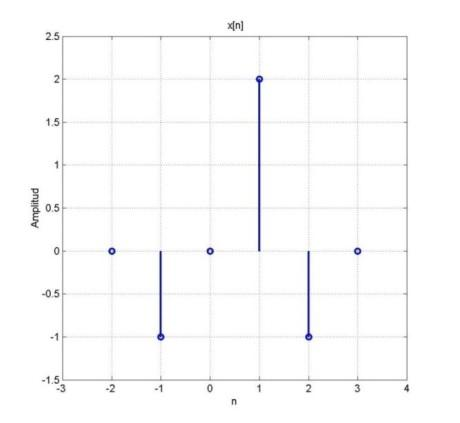

Realizar lo mismo con b), c) y d).

% open ('script_02_02.m')
script_02_02 ()

# Referencias

- I Nogueras GB. **Introducción informal a Matlab y Octave**. 2007.

- Oppenheim, Alan V.; Willsky, Alan S.; Nawab, S. Hamid. ***Señales y sistemas***. Pearson Educación, 1998.

- Mat.caminos.upm.es. ***Lenguaje de programación - MateWiki***. Available at:  [https://mat.caminos.upm.es/wiki/Lenguaje_de_programaci%C3%B3n#Tipado_est.C3.A1tico_y_din.C3.A1mico](https://mat.caminos.upm.es/wiki/Lenguaje_de_programaci%C3%B3n#Tipado_est.C3.A1tico_y_din.C3.A1mico). Universidad Politécnica de Madrid. 2017.